Vine Robot Modeling

clear, close all
syms L_k1 L_k2 L_k3 r

%Might need to define phi_kj
    phi_kj = 0;
    
    %Length matrix
    L_k = [L_k1 L_k2 L_k3]';
    
    %Length of center
    L_ck = (L_k1+L_k2+L_k3)/3;
    
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
    
    Q_k = [L_ck theta_k beta_k]';
    
    delta_kj = r*cos(phi_kj-theta_k);
    
    %How to calculate the length of each actuator
    L_kj = L_ck-delta_kj*beta_k;
    
    rho_k = beta_k/L_ck;
    
    R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
           (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
           -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
    
    %This does not work when all lengths are equal
    P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    T_k = [R_k P_k
           0 0 0 1];
    T_k(1,1);
   diff(T_k(1,1),L_k1);





## Forward Kinematic Model

clear, close all

%Start by definine a radius
r_real = 5*2/pi/2; %From my actual vine robot

%Now define start positions for all three actuators
act_11_start = [r_real 0 0 1]';
act_12_start = [r_real*cos(2*pi/3) r_real*sin(2*pi/3) 0 1]';
act_13_start = [r_real*cos(4*pi/3) r_real*sin(4*pi/3) 0 1]';

%Define a bas ecoordinate system
Base_coord = [1 0 0 0
              0 1 0 0
              0 0 1 0
              0 0 0 1];

%Function that gives a transformation matrix and actuator endpoints given
%actuator lengths and total actuator start point
%Also calculate next reference frame 
[T_01,act_11_end, act_12_end, act_13_end] = gen_transform(4,6,8,r_real,act_11_start,act_12_start,act_13_start,Base_coord);
T1 = Base_coord*T_01

T1 =     0.3396    0.3813    0.8598    3.1532
    0.3813    0.7799   -0.4964   -1.8205
   -0.8598    0.4964    0.1195    4.1054
         0         0         0    1.0000


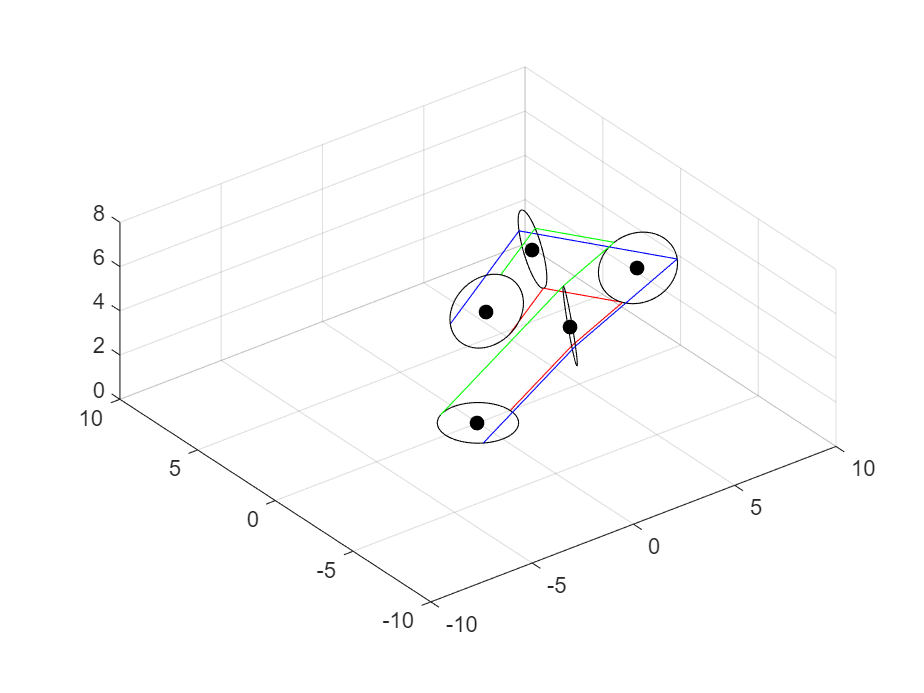

[T_12,act_21_end, act_22_end, act_23_end] = gen_transform(4,8,4,r_real,act_11_start,act_12_start,act_13_start,T1);
T2 = T1*T_12;
[T_23,act_31_end, act_32_end, act_33_end] = gen_transform(4,8,4,r_real,act_11_start,act_12_start,act_13_start,T2);
T3 = T2*T_23;
[T_34,act_41_end, act_42_end, act_43_end] = gen_transform(4,8,4,r_real,act_11_start,act_12_start,act_13_start,T3);
T4 = T3*T_34;

%Find coordinates of center of robot
T0_xyz = [Base_coord(1,4),Base_coord(2,4),Base_coord(3,4)]';
T1_xyz = [T1(1,4),T1(2,4),T1(3,4)]';
T2_xyz = [T2(1,4),T2(2,4),T2(3,4)]';
T3_xyz = [T3(1,4),T3(2,4),T3(3,4)]';
T4_xyz = [T4(1,4),T4(2,4),T4(3,4)]';


figure
%Plot coordinates of center of robot and format

%Yes, I know there is a lot of repeated code here, feel free to make it
%more efficient as long as the functionality does not change. 
plot3(T0_xyz(1),T0_xyz(2),T0_xyz(3),'.','MarkerSize',20,'Color','black')
axis equal
grid on
xlim([-10 10])
ylim([-10 10])
zlim([0 8])
hold on
plot3(T1_xyz(1),T1_xyz(2),T1_xyz(3),'.','Markersize',20,'Color','black')
plot3(T2_xyz(1),T2_xyz(2),T2_xyz(3),'.','Markersize',20,'Color','black')
plot3(T3_xyz(1),T3_xyz(2),T3_xyz(3),'.','Markersize',20,'Color','black')
plot3(T4_xyz(1),T4_xyz(2),T4_xyz(3),'.','Markersize',20,'Color','black')

%Plot four circles from the actuator end points
circle(act_11_start(1:end-1)',act_12_start(1:end-1)',act_13_start(1:end-1)','black')
circle(act_11_end(1:end-1)',act_12_end(1:end-1)',act_13_end(1:end-1)','black')
circle(act_21_end(1:end-1)',act_22_end(1:end-1)',act_23_end(1:end-1)','black')
circle(act_31_end(1:end-1)',act_32_end(1:end-1)',act_33_end(1:end-1)','black')
circle(act_41_end(1:end-1)',act_42_end(1:end-1)',act_43_end(1:end-1)','black')

%For now, plot lines denating where actuators are. This should be replaced
%with arcs later
plot3([act_11_start(1) act_11_end(1)],[act_11_start(2) act_11_end(2)],[act_11_start(3) act_11_end(3)],'Color','red')
plot3([act_12_start(1) act_12_end(1)],[act_12_start(2) act_12_end(2)],[act_12_start(3) act_12_end(3)],'Color','green')
plot3([act_13_start(1) act_13_end(1)],[act_13_start(2) act_13_end(2)],[act_13_start(3) act_13_end(3)],'Color','blue')

plot3([act_11_end(1) act_21_end(1)],[act_11_end(2) act_21_end(2)],[act_11_end(3) act_21_end(3)],'Color','red')
plot3([act_12_end(1) act_22_end(1)],[act_12_end(2) act_22_end(2)],[act_12_end(3) act_22_end(3)],'Color','green')
plot3([act_13_end(1) act_23_end(1)],[act_13_end(2) act_23_end(2)],[act_13_end(3) act_23_end(3)],'Color','blue')

plot3([act_21_end(1) act_31_end(1)],[act_21_end(2) act_31_end(2)],[act_21_end(3) act_31_end(3)],'Color','red')
plot3([act_22_end(1) act_32_end(1)],[act_22_end(2) act_32_end(2)],[act_22_end(3) act_32_end(3)],'Color','green')
plot3([act_23_end(1) act_33_end(1)],[act_23_end(2) act_33_end(2)],[act_23_end(3) act_33_end(3)],'Color','blue')

plot3([act_31_end(1) act_41_end(1)],[act_31_end(2) act_41_end(2)],[act_31_end(3) act_41_end(3)],'Color','red')
plot3([act_32_end(1) act_42_end(1)],[act_32_end(2) act_42_end(2)],[act_32_end(3) act_42_end(3)],'Color','green')
plot3([act_33_end(1) act_43_end(1)],[act_33_end(2) act_43_end(2)],[act_33_end(3) act_43_end(3)],'Color','blue')


%How to calculate turn angle based on rotation matrix
%angle = acos((trace(R_k)-1)/2)*180/pi
%length1 = norm(act_1_old-act_1_new)
%length2 = norm(act_2_old-act_2_new)
%length3 = norm(act_3_old-act_3_new)


%The next step is to convert between task space and joint space
    %


%Function for creating a transformation matrix based on actuator length
%inputs, and a radius input 

%Feel free to add outputs as needed to generate graphs

function [T_k, act_1_end ,act_2_end ,act_3_end] = gen_transform(L_k1,L_k2,L_k3,r,act_1_start,act_2_start,act_3_start,T_prev)

    %Credit to https://doi.org/10.1038/s41467-024-54327-6 for the modeling
    %walkthrough
    
    
  
    %Might need to define phi_kj
    phi_kj = 0;
    
    %Length matrix
    L_k = [L_k1 L_k2 L_k3]';
    
    %Length of center
    L_ck = (L_k1+L_k2+L_k3)/3;
    
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
    
    Q_k = [L_ck theta_k beta_k]';
    
    delta_kj = r*cos(phi_kj-theta_k);
    
    %How to calculate the length of each actuator
    L_kj = L_ck-delta_kj*beta_k;
    
    rho_k = beta_k/L_ck;
    
    R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
           (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
           -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
    
    %This does not work when all lengths are equal
    P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    T_k = [R_k P_k
            0 0 0 1];


    %Find actuator position because it looks cool
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
    
    
end


%Functions that I modified from chatGPT to help with visualization



%Function that plots an arc based on end points and curvature. This does
%not work as intended as there are 2 possible arc positions
function arc(p1,p2,kappa,color)
      % Curvature (positive = left turning)
    % Calculate radius
    R = 1 / abs(kappa);
    % Vector from p1 to p2
    chord = p2 - p1;
    L = norm(chord);
    midpoint = (p1 + p2) / 2;
    % Normal to the plane: if not provided, choose a default
    % You can define a plane normal (e.g., z-axis), or use an auxiliary point
    % For simplicity, we'll define it to be perpendicular to chord in Z-up space
    if all(cross(chord, [0 0 1]) == 0)
        plane_normal = [0 1 0];  % Avoid degenerate case
    else
        plane_normal = cross(chord, [0 1 0]);
    end
    plane_normal = plane_normal / norm(plane_normal);
    % Perpendicular direction within plane
    dir = chord / L;
    perp = cross(plane_normal, dir);
    perp = perp / norm(perp);
    % Distance from midpoint to center
    h = sqrt(R^2 - (L/2)^2);
    center = midpoint + sign(kappa) * h * perp;
    % Compute arc angle range
    v1 = p1 - center;
    v2 = p2 - center;
    theta1 = 0;
    theta2 = acos(dot(v1, v2) / (norm(v1) * norm(v2)));
    % Ensure direction of arc matches curvature
    if dot(cross(v1, v2), plane_normal) < 0
        theta2 = -theta2;
    end
    % Create arc
    N = 100;
    theta = linspace(theta1, theta2, N);
    arc = zeros(N, 3);
    v1_norm = v1 / norm(v1);
    for i = 1:N
        rot_axis = plane_normal;
        angle = theta(i);
        rot_axis = rot_axis / norm(rot_axis);
        v_rot = v1_norm*cos(angle) + cross(rot_axis, v1_norm)*sin(angle) + rot_axis*dot(rot_axis,v1_norm)*(1 - cos(angle));
        arc(i, :) = center + v_rot * R;
    end
    % Plot
    plot3(arc(:,1), arc(:,2), arc(:,3),'-','Color',color);
end

%Function for drawing a circle from 3 points
function circle(P1,P2,P3,color)
    % Step 1: Calculate vectors for the sides of the triangle
    v12 = P2 - P1;
    v13 = P3 - P1;
    % Step 2: Compute the normal vector to the plane
    normal = cross(v12, v13);
    normal = normal / norm(normal);  % Normalize
    % Step 3: Compute the midpoints of the sides
    mid12 = (P1 + P2) / 2;
    mid13 = (P1 + P3) / 2;
    % Step 4: Find the direction vectors of the perpendicular bisectors
    perp12 = cross(normal, v12);
    perp13 = cross(normal, v13);
    % Step 5: Find the intersection of the perpendicular bisectors (circumcenter)
    % Parametrize the perpendicular bisectors to find their intersection
    % Line 1: mid12 + t1 * perp12
    % Line 2: mid13 + t2 * perp13
    A = [perp12; -perp13]';  % Coefficients for the system of equations
    b = mid13 - mid12;       % The difference vector
    % Solve the system of linear equations to find t1 and t2
    t = A \ b';
    % Find the circumcenter (intersection point)
    circumcenter = mid12 + t(1) * perp12;
    % Step 6: Calculate the radius (distance from circumcenter to any point)
    radius = norm(circumcenter - P1);
    % Step 7: Parametrize the circle
    theta = linspace(0, 2*pi, 200);  % Parameter for the circle
    u = v12 / norm(v12);             % First direction in the plane
    v = cross(normal, u);            % Second direction in the plane
    v = v / norm(v);                 % Normalize to make orthonormal
    % Circle points
    circle3D = circumcenter' + radius * (u' * cos(theta) + v' * sin(theta));   
    % Plot
    plot3(circle3D(1,:), circle3D(2,:), circle3D(3,:), '-','Color',color);
end



## Inverse Kinematics

%Two ideas: linearization and optimization

%We can model the dynamics, and maybe linearize?
%This might be a good idea for the class project
%We can use our kinematic model and combine it with this linearization
%approach maybe https://journals.sagepub.com/doi/full/10.1177/0278364921997167

%Alternatively, 

%The state is the end effector position, and the inputs are 
%Inputs are forces that create torques, derived from actuator dynamics
    %Need some way to model elasticity of the actuators?


%define ub and lb

%create function nonlcon that is forward kinematic
%Create min function that is some useful function like minimizing length of
%each actuator



%Use fmincon and see what happens?

%Lets try one section for now?
lb = [4 4 4];
ub = [8 8 8];




x0 = [5 5 5.5];

p_desired = T1;
nonlcon = @(x) forwardkin(x,p_desired);
goal = @(x)x(1)+x(2)+x(3);
A = [];
b = [];
Aeq = [];
beq = [];  

x = fmincon(goal,x0,A,b,Aeq,beq,lb,ub,nonlcon)   


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     4.0000    6.0000    8.0000


%Weird
[T_Test,act_11_end, act_12_end, act_13_end] = gen_transform(x(1),x(2),x(3),r_real,act_11_start,act_12_start,act_13_start,Base_coord);

T1

T1 =     0.3396    0.3813    0.8598    3.1532
    0.3813    0.7799   -0.4964   -1.8205
   -0.8598    0.4964    0.1195    4.1054
         0         0         0    1.0000


T_Test

T_Test =     0.3396    0.3813    0.8598    3.1532
    0.3813    0.7799   -0.4964   -1.8205
   -0.8598    0.4964    0.1195    4.1054
         0         0         0    1.0000




function [c,ceq] = forwardkin(x,p_des)
    %Might need to define phi_kj
    r = 5*2/pi/2; %From my actual vine robot
    % p_des = [0.548302705533194	0.469417598194745	0.692106394718367	2.44425514465134
    %         0.469417598194745	0.512166921975850	-0.719258063937319	-2.54014445831864
    %         -0.692106394718367	0.719258063937319	0.0604696275090439	3.74517323140791
    %         0	0	0	1]; %Need to figure out how to pass it in
    %phi_kj = 0;
    %Length matrix
    %L_k = [L_k1 L_k2 L_k3]';
    L_k1 = x(1);
    L_k2 = x(2);
    L_k3 = x(3);
    %Length of center
    L_ck = (L_k1+L_k2+L_k3)/3;
    
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
    
    %Q_k = [L_ck theta_k beta_k]';
    
    %delta_kj = r*cos(phi_kj-theta_k);
    
    %How to calculate the length of each actuator
    %L_kj = L_ck-delta_kj*beta_k;
    
    rho_k = beta_k/L_ck;
    
    R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
           (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
           -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
    %This does not work when all lengths are equal
    P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    T_k = [R_k P_k
            0 0 0 1];

    c = T_k-p_des;

    ceq = [];

end